# Discritisation

Disctitising the state equations for both temperature, SoC, and RC. S.t

xdot = f(x,i)

v_out = f(x(2)) + iR0 + x(3)

delta_temp =  clear

clear
file_loc = "..\..\..\cycle_exports\MOLI_28\";
cycle_number = "46";
filepath = strcat(file_loc, sprintf("MOLI_cycle_%s.mat", cycle_number));
load(SolutionLoader("MOLI_28/",2));
try
    solution_unbound
catch exception
    disp("Mhmmmmm")
end

solution_unbound = struct with fields:
            multipliers: [1×1 struct]
       computation_time: 19.4294
                      z: [792×1 double]
                   coll: [1×1 struct]
                      X: [130×2 double]
                      U: [130×1 double]
                      T: [130×1 double]
                      p: [13×1 double]
                     x0: [2×1 double]
                     t0: 0
                     tf: 1.3150e+04
                   Tdec: [130×1 double]
             z_orgscale: [792×1 double]
                   cost: [1×1 struct]
                    org: [1×1 struct]
                     dX: [258×2 double]
                     dU: [258×1 double]
                     Xp: {2×1 cell}
                    dXp: {2×1 cell}
                     Up: {[1×1 struct]}
                    dUp: {[1×1 struct]}
                  Error: [258×2 double]
                T_error: [259×1 double]
          ErrorRelative: [258×2 double]
        ConstraintError: [1300×6 double]
   

solution_unbound.p = [solution_unbound.p; 0.1; 80];
solution = solution_temp;


time = 0:1:14000;
i_input = interp1(tt,u1',time,"previous");
i_size = length(i_input);
v1 = ones(1,i_size)*0.05;
z = ones(1,i_size);
DT = zeros(1,i_size);
states = [v1; z; DT];

params = length(solution.p)

params = 15

Ts = time(end) - time(end-1)

Ts = 1

for i = 1:i_size-1
i_curr = i_input(i);
[A, B] = discrit(solution.p,Ts);
states(:,i+1) = A*states(:,i) + B*[i_curr;i_curr.^2;states(1,i).*i_curr];
end
Sim_DT = states(3,:)

Sim_DT =          0   -0.0011   -0.0021   -0.0032   -0.0042   -0.0052   -0.0062   -0.0072   -0.0082   -0.0092   -0.0101   -0.0111   -0.0120   -0.0130   -0.0139   -0.0148   -0.0157   -0.0166   -0.0175   -0.0183   -0.0192   -0.0200   -0.0209   -0.0217   -0.0225   -0.0233   -0.0241   -0.0249   -0.0257   -0.0264   -0.0272   -0.0279   -0.0287   -0.0294   -0.0301   -0.0308   -0.0315   -0.0322   -0.0328   -0.0335   -0.0342   -0.0348   -0.0354   -0.0361   -0.0367   -0.0373   -0.0379   -0.0384   -0.0390   -0.0396


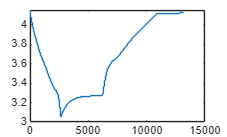

fix.poly.xe = zeros(params - 6,1);
Sim_V = polymodel(fix,solution.p,states(2,:),1)  + states(1,:) + i_input.*(solution.p(params-3));
stairs(time,Sim_V)

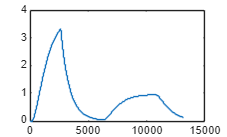

stairs(time,Sim_DT)

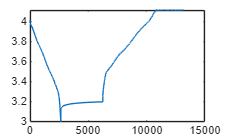


plot(tt,y)

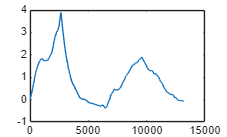

plot(tt,tp)

%[trr,trw] = discrit_solver(t_input,i_input,solution_unbound.p,1)